% Week 11 example code for training a simple CNN classifier on the
% CUB_200_2011_Subset20classes dataset. Instead of using the full images,
% we only use the bounding box area defined in bounding_boxes.txt.
%
% Authors: Roland Goecke and James Ireland.
% Date created: 02/05/2022
% Modified by Ibrahim Radwan
% Date last updated: 11/04/25

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the training, validation and test partitions from the relevant

%folder = "Data\CUB_200_2011_Subset20classes\";
%folder = "P:\CUB_200_2011_Subset20classes\";
%folder = "/Users/s423738/Dropbox/UC/Teaching/8890_CVIA_PG/2022/Data/CUB_200_2011_Subset20classes/";
folder = "H:\computer-vision\assignment_1\data\CUB_200_2011_Subset20classes\";
trainingImageNames = readtable(fullfile(folder, "train.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ...
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);
disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
labelsValidation = arrayDatastore(validationImageDS.Labels);
labelsTest = arrayDatastore(testImageDS.Labels);

cdsTraining = combine(trainingImageDS, labelsTraining);
cdsValidation = combine(validationImageDS, labelsValidation);
cdsTest = combine(testImageDS, labelsTest);

% Resize all images to a common width and height
targetSize = [224, 224];
cdsTraining = transform(cdsTraining, @(x) preprocessData(x,targetSize));
cdsValidation = transform(cdsValidation, @(x) preprocessData(x,targetSize));
cdsTest = transform(cdsTest, @(x) preprocessData(x,targetSize));

## Display a sample image from the datastore

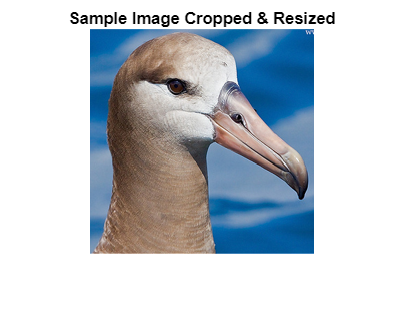

figure(1);
imshow(cdsTraining.read{1});
title('Sample Image Cropped & Resized');

## Create a simple CNN

layers = [
    imageInputLayer([224 224 3])    % This needs to match the image size chosen above

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Set the training options

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'MiniBatchSize', 20, ...
    'MaxEpochs', 10, ...
    'Verbose', true, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1, ...
    'ValidationData', cdsValidation, ...
    'Plots','training-progress');

## Train the simple CNN model

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:22 |        5.00% |        6.76% |       3.2591 |       3.8560 |          0.0010 |
|       1 |           2 |       00:00:23 |       20.00% |              |       3.6174 |              |          0.0010 |
|       1 |           3 |       00:00:25 |       10.00% |              |       3.8386 |              |          0.0010 |
|       1 |           4 |       00:00:27 |       10.00% |              |       4.4651 |   

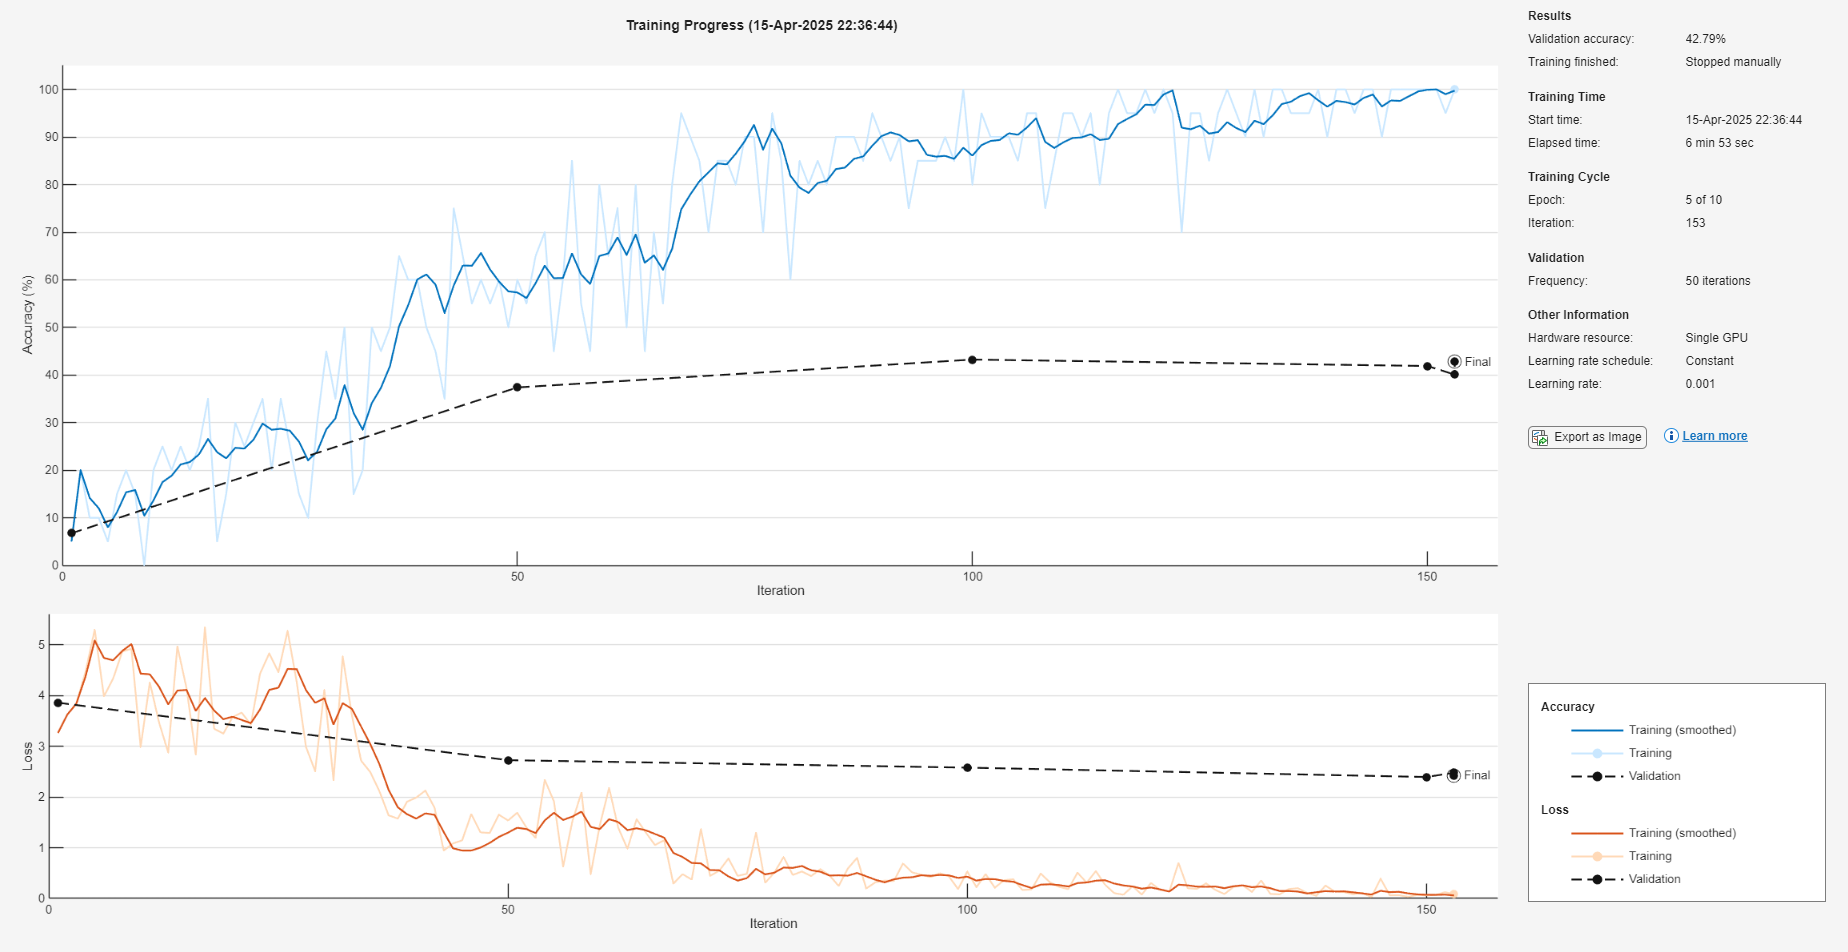

simpleCNN = trainNetwork(cdsTraining, layers, options);

## Test the accuracy on the test partition

YPred = classify(simpleCNN, cdsTest);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.4730

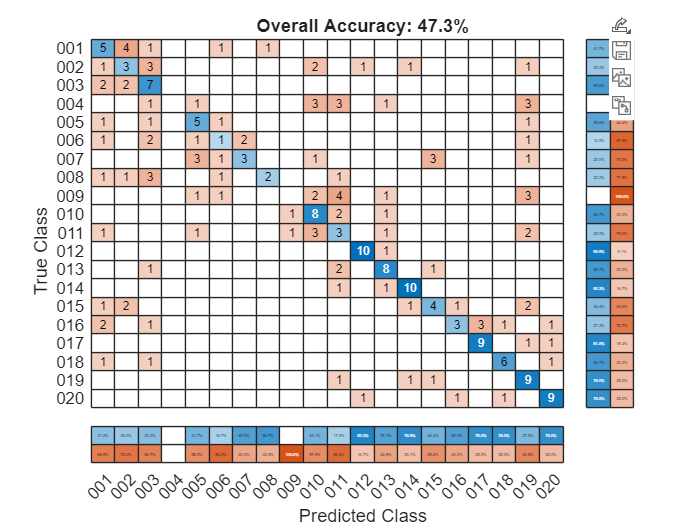


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

classwisePosRecog = zeros(height(order), 1);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog(iI) = round(100 * m(iI, iI) / samplesPerRow(iI), 1);
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog)

   41.7000
   25.0000
   63.6000
         0
   55.6000
   12.5000
   25.0000
   22.2000
         0
   66.7000
   25.0000
   90.9000
   66.7000
   83.3000
   36.4000
   27.3000
   81.8000
   66.7000
   75.0000
   75.0000



## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
try
    data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
    data_out{2} = data{2};  % Keep labels as they are
catch e
    % This is solely for debugging
    disp(e)
end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
image_box_map = containers.Map;
for i = 1:size(ImageNames, 1)
    fn = ImageNames{i,2}{1};
    fn = split(fn, "\");
    fn = split(fn, "/");
    image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
end
end